defaultDir = 'M:\Projects and Analysis\Papers\P2ry1'; %change if in a different location
cd(defaultDir);
addpath(genpath('MATLAB Functions'));
cd(['Fig 3 - ISCs and IHCs']);


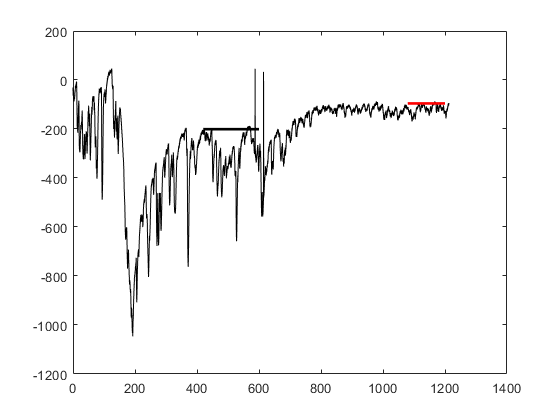

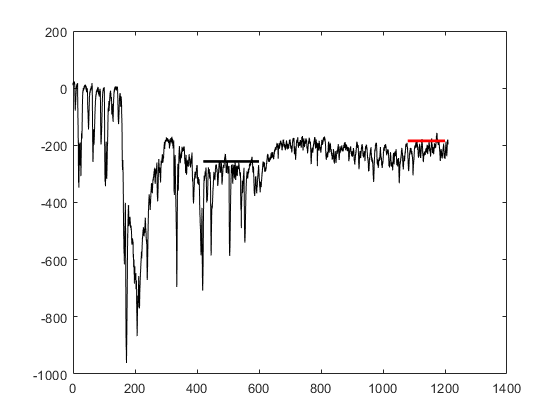

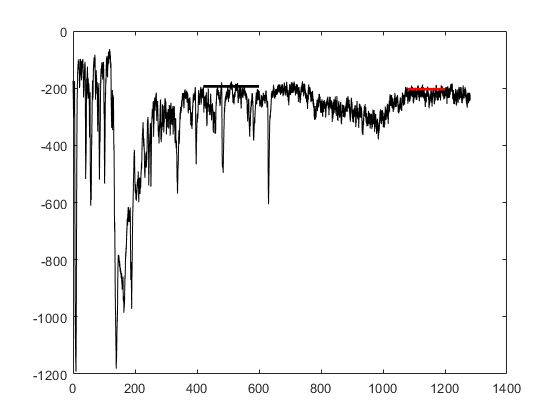

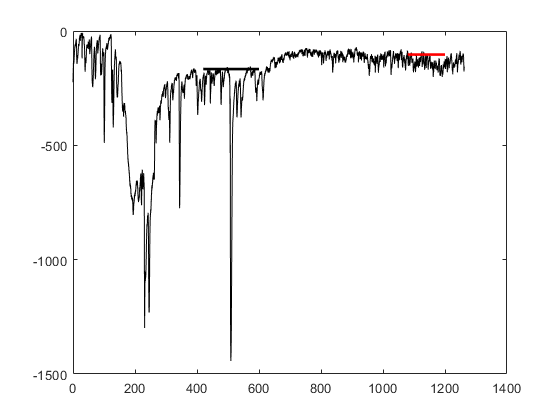

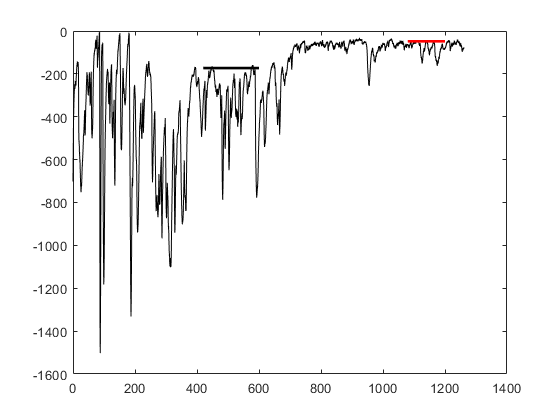

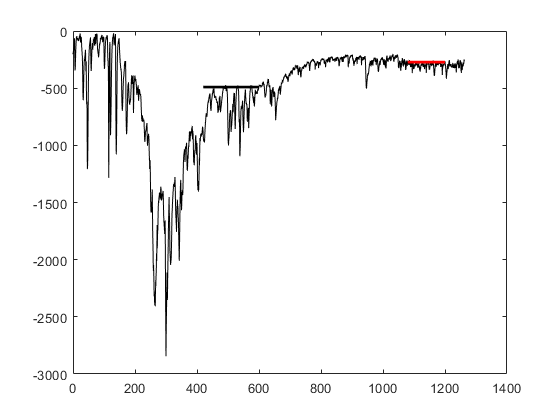

%%run ephys analysis
blocktail_cells = getStats_Blocktail('.\Data\WT_Blocktail*',[1 1 1],1);

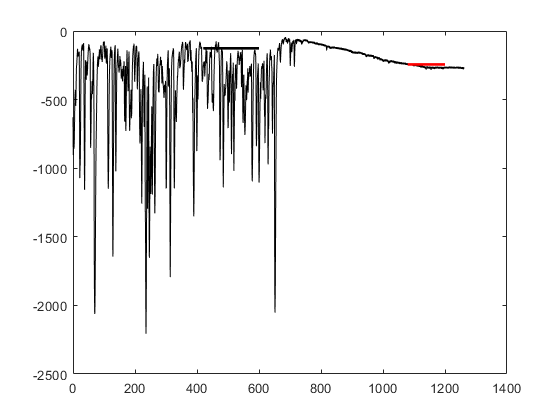

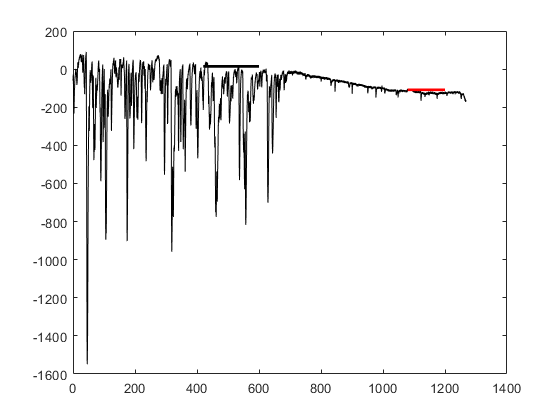

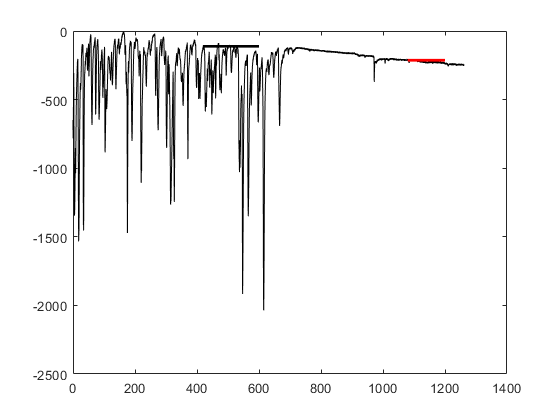

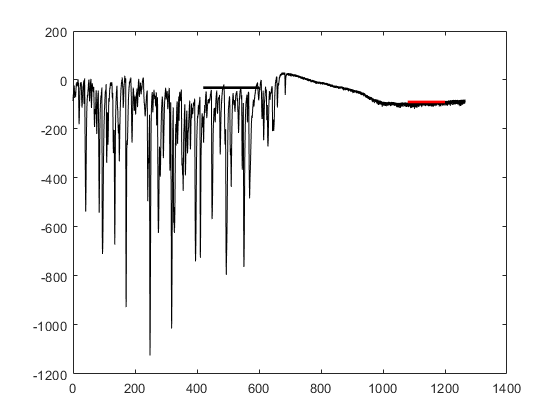

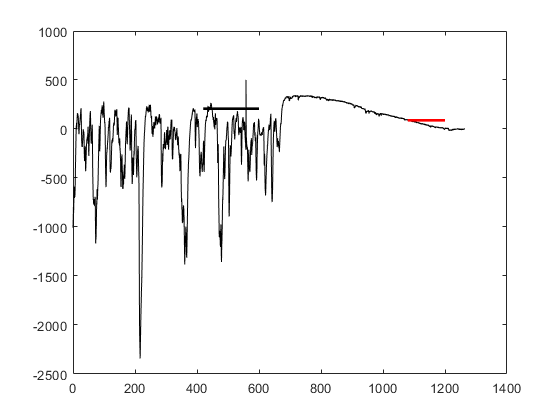

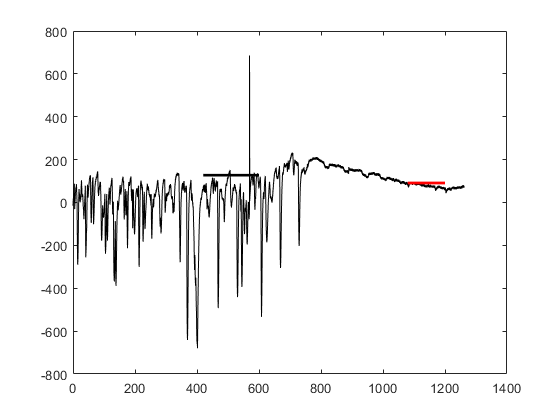

MRScells = 1×6 struct array with fields:
    breakinR
    preR
    postR
    Vm
    inwardCurrent
    d
    time
    minPt


%CdTTXcells = getStats_Blocktail('.\Data\WT_CdTTX*',[1 1 1],450+180);
MRScells = getStats_Blocktail('.\Data\WT_MRS*',[1 1 1],450)

%%load structs
blocktail_cells = loadCellStructs('.\Data\WT_Blocktail_MRS\*\*stats.mat');
MRS_cells = loadCellStructs('.\Data\WT_MRS\*\*stats.mat');

dname = '.\Data\WT_Blocktail_MRS';
fileList = loadFileList([dname '\*\*_gfv.abf']);

tempd = [];
for i = 1:size(fileList,1)
    [d,time,si] = loadPclampData(fileList{i});
    timepts = time >= 0 & time <= 1200;
    
    calctps = time >=450+180 & time <= 500+180;
    sstps = time >= 800+180 & time <= 900+180;
    max(i) = prctile(d(calctps),95);
    min(i) = mean(d(sstps));
    
    temporig(i,:) = d(time <= 0 & time <= 1200);
    tempd(i,:) = smooth(d(timepts) - max(i));
end

** abfload
opening M:\Projects and Analysis\Papers\P2ry1\Figure 3 - ISCs and IHCs\Data\WT_Blocktail_MRS\190507_Cell1\19507006_gfv.abf..
recording mode of data must be event-driven variable-length (1), event-driven fixed-length (2) or gap-free (3) -- returning empty matrix


Error using  / 
Matrix dimensions must agree.

Error in loadPclampData (line 6)
    samplingRateHz = 1/(samplingRateus*10^-6);


 display(['Average inward current:' num2str(mean(max-min)) ' +/- ' num2str(sterr(max-min,2)) ' pA.']);


figure(1); hold off;

%plot(time(timepts),tempd,'Color',[0.8 0.8 0.8],'LineWidth',0.5); hold on;
plot(time(timepts),mean(tempd,1),'Color','k','LineWidth',1.5);

Undefined function or variable 'timepts'.

xlim([000 1200]);
%ylim([-800 50]);
%figQuality(gcf,gca,[3 2]);
%export_fig('.\EPS Panels\Supp_MRSgroup.eps')

dname = '.\Data\WT_CdTTX_MRS';
fileList = loadFileList([dname '\*\*_gfv.abf']);

tempd = []; temporig = []; max = []; min = [];
for i = 1:size(fileList,1)
    [d,time,si] = loadPclampData(fileList{i});
    timepts = time >= 0 & time <= 1200;
    
    calctps = time >=450+180 & time <= 500+180;
    sstps = time >= 800+180 & time <= 900+180;
    max(i) = prctile(d(calctps),95);
    min(i) = mean(d(sstps));
    
    temporig(i,:) = d(time <= 0 & time <= 1200);
    tempd(i,:) = smooth(d(timepts) - max(i));
end

 display(['Average inward current:' num2str(mean(max-min)) ' +/- ' num2str(sterr(max-min,2)) ' pA.']);

Average inward current:NaN +/-  pA.


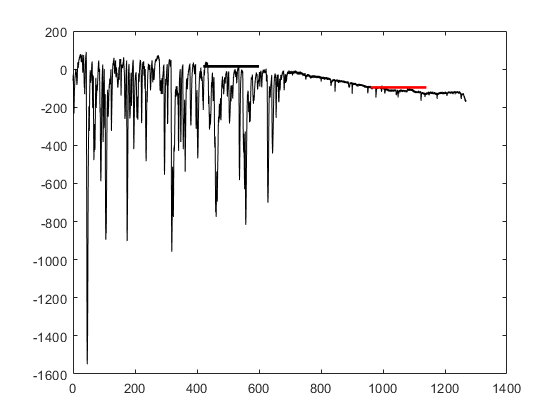

Undefined function or variable 'timepts'.

 figure(1);hold on; plot(time(timepts),mean(tempd,1),'Color','r','LineWidth',1.5);

dname = '.\Data\WT_MRS';
fileList = loadFileList([dname '\*\*_gfv.abf']);

tempd = [];
for i = 1:size(fileList,1)
    [d,time,si] = loadPclampData(fileList{i});
    
    timepts = time >= 0 & time <= 900;
    
    calctps = time >=450 & time <= 550;
    sstps = time >= 800 & time <= 900;
    max(i) = prctile(d(calctps),95);
    min(i) = mean(d(sstps));
    
    temporig(i,:) = d(time <= 0 & time <= 900);
    tempd(i,:) = smooth(d(timepts) - max(i));
end

 display(['Average inward current:' num2str(mean(max-min)) ' +/- ' num2str(sterr(max-min,2)) ' pA.']);

Average inward current:110.2737 +/- 43.6553 pA.


 %%

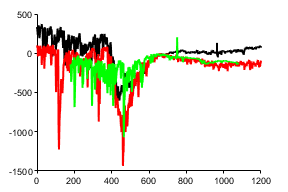


 figure(1); hold on;
%plot(time(timepts),tempd,'Color',[0.8 0.8 0.8],'LineWidth',0.5); hold on;
plot(time(timepts)+180,mean(tempd,1),'Color','g','LineWidth',1.5);
xlim([000 1200]);
%ylim([-800 50]);
figQuality(gcf,gca,[3 2]);

%export_fig('.\EPS Panels\Supp_MRSgroup.eps')


dname = '..\Figure 2 - ISCs\Data\WT_MRS_PPADs_RT';
fileList = loadFileList([dname '\*.abf']);

tempd = [];
for i = 1:size(fileList,1)
    [d,time,si] = loadPclampData(fileList{i});
    
    timepts = time >= 0 & time <= 900;
    
    calctps = time >=450 & time <= 550;
    sstps = time >= 800 & time <= 900;
    max(i) = prctile(d(calctps),95);
    min(i) = mean(d(sstps));
    
    temporig(i,:) = d(time <= 0 & time <= 900);
    tempd(i,:) = smooth(d(timepts) - max(i));
end

 display(['Average inward current:' num2str(mean(max-min)) ' +/- ' num2str(sterr(max-min,2)) ' pA.']);
 %%


dname = '.\Data\WT_Blocktail_MRS';
fileList = loadFileList([dname '\*\*_gfv.abf']);

[d, time] = loadPclampData(fileList{1});
figure; plot(time,d+200,'Color','k');
figQuality(gcf,gca,[5 3]);
xlim([0 1200]);
ylim([-1000 100]);
export_fig('.\EPS Panels\Blocktailexample.eps')

dname = ['.\Data\WT_CdTTX_MRS'];
fileList = loadFileList([dname '\*\*_gfv.abf']);
[d, time, si] = loadPclampData(fileList{2});
figure; plot(time,d,'Color','k');
xlim([0 1200]);
ylim([-1000 100]);

figQuality(gcf,gca,[5 3]);
export_fig('.\EPS Panels\CdTTXexample.eps')



h = compare2([MRS_cells.inwardCurrent]',[blocktail_cells.inwardCurrent]',{'+MRS2500','Blocktail'},'Change in baseline (pA)',[3 2]);

   2.6902e-04



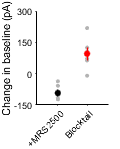

ylim([-150 300]);
yticks([-150:150:300])
xtickangle(45)
figQuality(gcf,gca,[1. 1.55]);

handleTheSubplot({h,h},[1 2]);

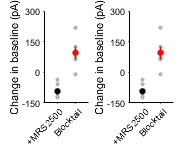

figQuality(gcf,gca,[2. 1.53]);
export_fig('.\EPS Panels\Summary_currents.eps');

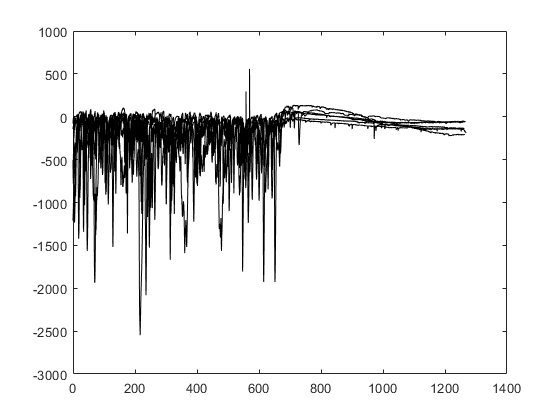

meanMRS = []; meanblock = [];
figure;
for i = 1:size(MRScells,2)
plot(MRScells(i).time,MRScells(i).d-MRScells(i).minPt,'Color','k','LineWidth',0.5); hold on;
time = MRScells(i).time;
meanMRS(i,:) = MRScells(i).d(time <=1200)-MRScells(i).minPt;
end

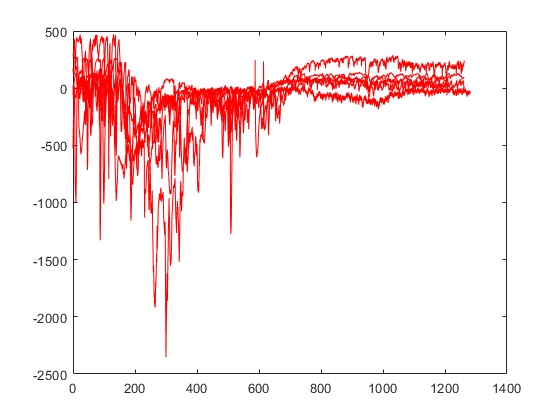


figure;
for i = 1:size(blocktail_cells,2)
plot(blocktail_cells(i).time,blocktail_cells(i).d-blocktail_cells(i).minPt,'Color','r','LineWidth',0.5); hold on;
meanblock(i,:) = blocktail_cells(i).d(time <=1200)-blocktail_cells(i).minPt;
end

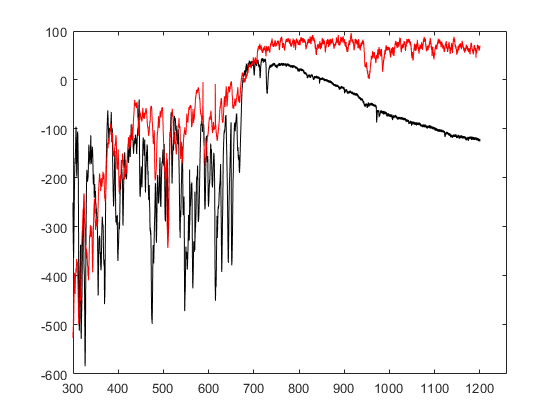

figure; plot(time(time<=1200),mean(meanMRS,1),'Color','k'); hold on;
plot(time(time<=1200),mean(meanblock,1),'Color','r');
xlim([300 1260]);

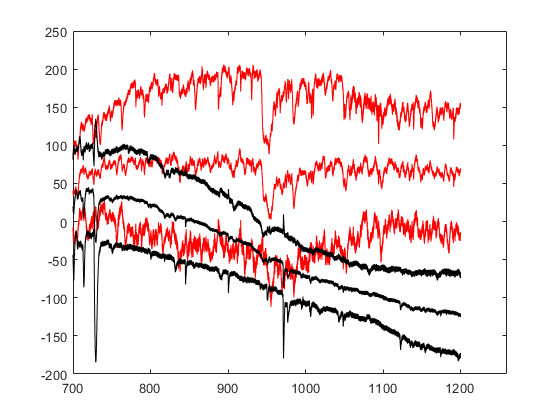


figure; plot(time(time<=1200),mean(meanblock,1),'Color','r'); hold on;
plot(time(time<=1200),mean(meanblock,1)+std(meanblock,[],1),'Color','r');
plot(time(time<=1200),mean(meanblock,1)-std(meanblock,[],1),'Color','r');
plot(time(time<=1200),mean(meanMRS,1),'Color','k');
plot(time(time<=1200),mean(meanMRS,1)+std(meanMRS,[],1),'Color','k');
plot(time(time<=1200),mean(meanMRS,1)-std(meanMRS,[],1),'Color','k');
xlim([700 1260]);


%shadedErrorBar(time(time<=1200),mean(meanMRS,1), std(meanMRS,[],1));

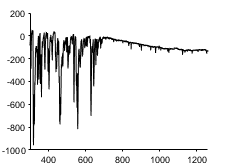

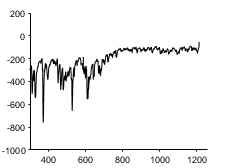

%%example plots
file = '.\Data\WT_MRS\190508_Cell2\19508016_gfv.abf';
[d,time] = loadPclampData(file);
figure; plot(time,d,'Color','k');
xlim([300 1260]);
ylim([-1000 200])
figQuality(gcf,gca,[2.4 1.75]);
export_fig('.\EPS Panels\WT_Example_MRS.eps')


file = '.\Data\WT_Blocktail_MRS\190507_Cell1\19507006_gfv.abf';
[d,time,fs] = loadPclampData(file);
figure; plot(time,lowpass(d,10,fs),'Color','k');
xlim([300 1260]);
ylim([-1000 200])
figQuality(gcf,gca,[2.4 1.75]);
export_fig('.\EPS Panels\WT_Example_MRS_blocktail.eps')